# TP1 Ex2  Loop shaping

## LTI transfer function

Let 


$$G(s)=\frac{1}{s^{2}+0.2683 s+5}$$


be a second order LTI transfer function. The goal is to design a controller K (s) for (3), based on the Loop-Shaping control strategy, in order to achieve satisfactory performances and to minimise the control effort as well as the effect of the measurement noise. The performances are specified in the frequency domain in terms of the steady-state error ε, the frequency bandwidth $w_b
$ and a maximum overshoot M. 

clear all 
clf 
num_G=1;
den_G=[1 0.2683 5];
G=tf(num_G,den_G);

### Sensitivity and Complementary sensitivity


$$\left\{\begin{array}{l}
S=\frac{1}{1+L} \\
T=\frac{L}{1+L}
\end{array}\right.$$



$$L=K(s) G(s)$$


- 
$$S+T=1
$$
   

- It is not possible to independently impose constraints on S and T.

With the block diagram

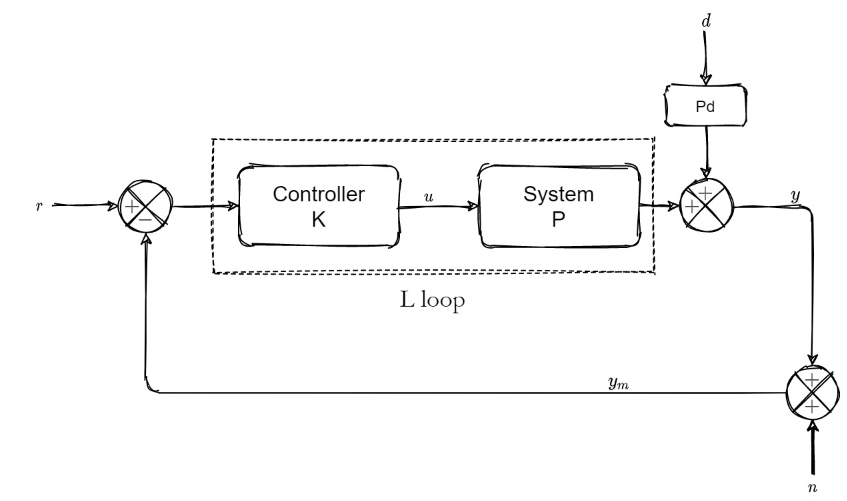

We can have the following relationship


$$y=Tr+S(P_dd)+Tn$$
 


$$u = \frac{K}{1+GK}(r-P_dd-n)=\frac{K}{1+L}(r-P_dd-n)$$


Where $r$ is the reference, $d$ is the disturbance, and $n
$ is the mesurement noise.

Now, to design the controller $$K(s),$$ such that the objectives mentioned above can be taken into account, Iet us define the following ***frequency weighting function***


$$$$
W_{1}(s)=\frac{\frac{1}{M} s+w_{b}}{s+w_b * \varepsilon}
$$$$


To achieve the following performances (for the closed-loop system)

-  A frequency bandwidth of $$w_{b}=1.5 \mathrm{rad} / \mathrm{s}$$

- A steady-state error of $$\varepsilon=10^{-4}$$ within the specified frequency bandwidth.

- Maximum overshoot $M
$ lower or equal to 2 

Let $$W_{2}=0.1$$ and $$W_{3}=0$$

W1 = makeweight(1000,1.5,0.5);
W2 = 0.1;
W3 = 0;

% the Bode Diagram of W1
bodemag(W1); grid on; 

#### Find the H∞ controller K (s) which can satisfy the above specifications. 

[`P`](https://www.mathworks.com/help/robust/ref/lti.augw.html#mw_da22b821-fed0-4a57-9260-65b997927967)` = augw(`[`G`](https://www.mathworks.com/help/robust/ref/lti.augw.html#mw_2bb242df-cce7-4a14-9bfa-00b9cacc37bc)`,`[`W1,W2,W3`](https://www.mathworks.com/help/robust/ref/lti.augw.html#f10-152038_sep_mw_e5076af4-3351-461b-bd3b-7e4c689415db)`)` computes a state-space model of an augmented LTI plant *P*(*s*) with the weighting functions *W*1(*s*), *W*2(*s*), and *W*3(*s*) penalizing the error signal, control signal, and output signal, respectively. `P` is the augmented plant of the following diagram.

Here, since the system is SISO and our goal is only to track the reference robustly, W3 is not necessary.

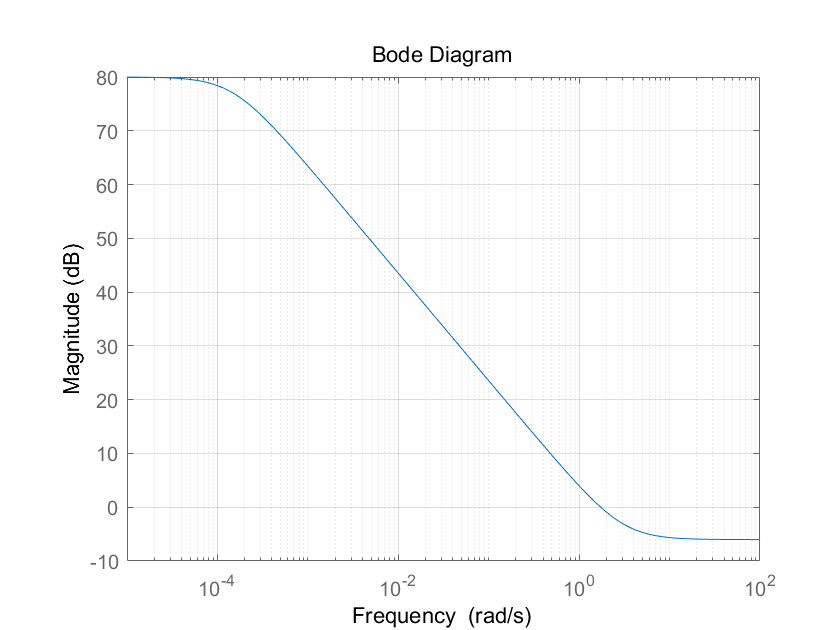

P = augw(G,W1,W2,W3);

[K,CL,gamma] = hinfsyn(P,1,1);
size(K)

- By drwaing the Bode Diagram of the L loop, one can see that the peak of the frequency domain response of the original device is smoothed out

clf
bodemag(G,G*K)
legend('G','G*K')

State-space model with 1 outputs, 1 inputs, and 3 states.


grid on 

- The sensitivity and complementary sensitivity 

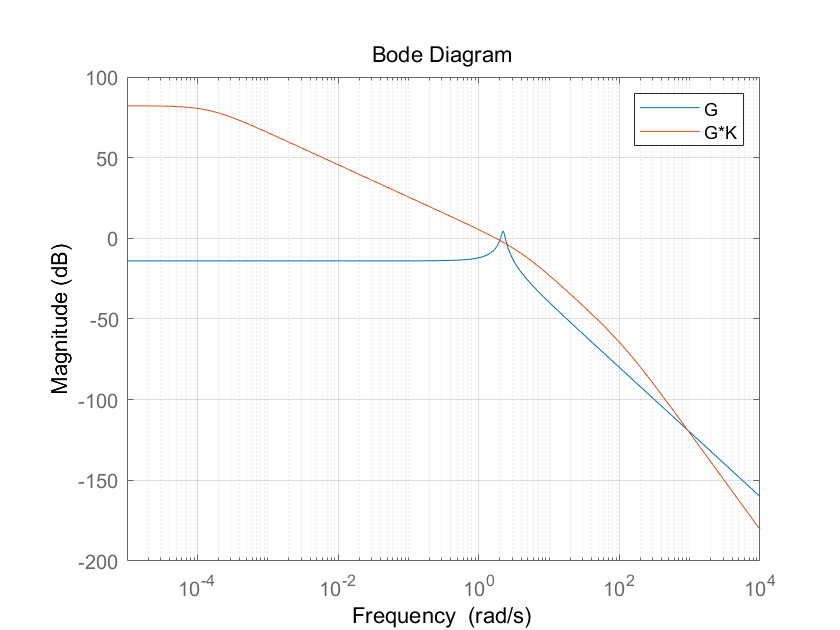

subplot(2,1,1)
bodemag(1/(1+G*K),1/G)
legend('CL with H-infinity controller','CL without controller')
title('S')

grid on 
subplot(2,1,2)
bodemag((G*K)/(1+G*K),G/(1+G))
legend('CL with H-infinity controller','CL without controller')
title('T')
grid on 


In the plot of  sensitivity S

- In the case without controller, S is high in both low and high frequencies bands, which means that the output disturbances will be amplified in the output, and also in the tracking error, with the controller, the disturbances can be reduced.

In the plot of complementary sensitivity T

- the H-infinity controller guarantees that the gain in low frequency band is 1, which is 0dB in the Bode plot, and the peak of the frequency domain response of the original device is smoothed out, both can assure small steady state error since the reference signal are generally in the low frequency band.

- We note also that the gain for high frequency band (>500Hz) is also reduced, which is good since the mesurement error has generally high frequency.

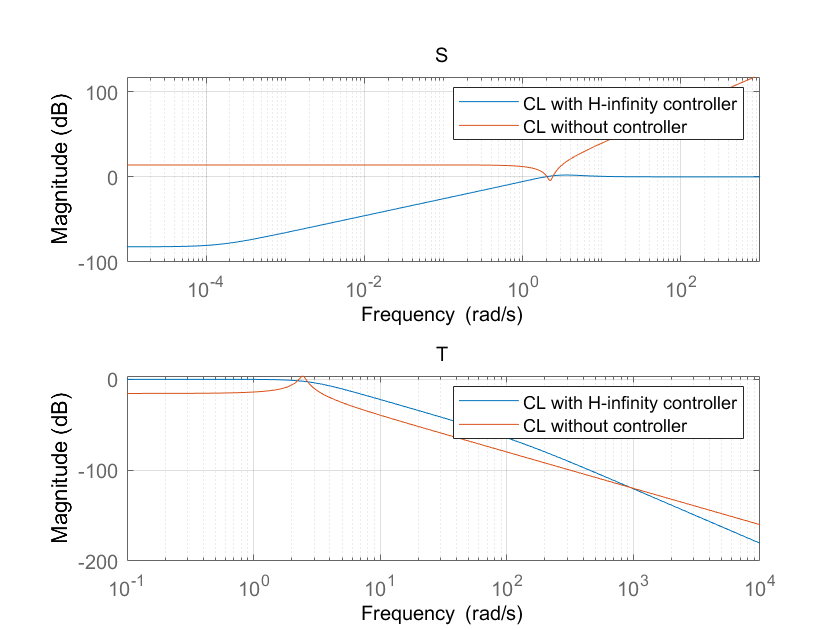

figure()
bodemag(K/(1+G*K),1/(1+G))
legend('CL with H-infinity controller','CL without controller')
title('d2u\n2u\r2u')

grid on 

- This plot shows the frequency domain response of the transfer between reference, mesurement noise, ouput-disturbance and the control input.

- One can see that the noises in high frequencies are reduced.

- ........

gamma
% sigma(CL,ss(gamma))
% ylim([-20,20]);


Try another configuration of desired  performances

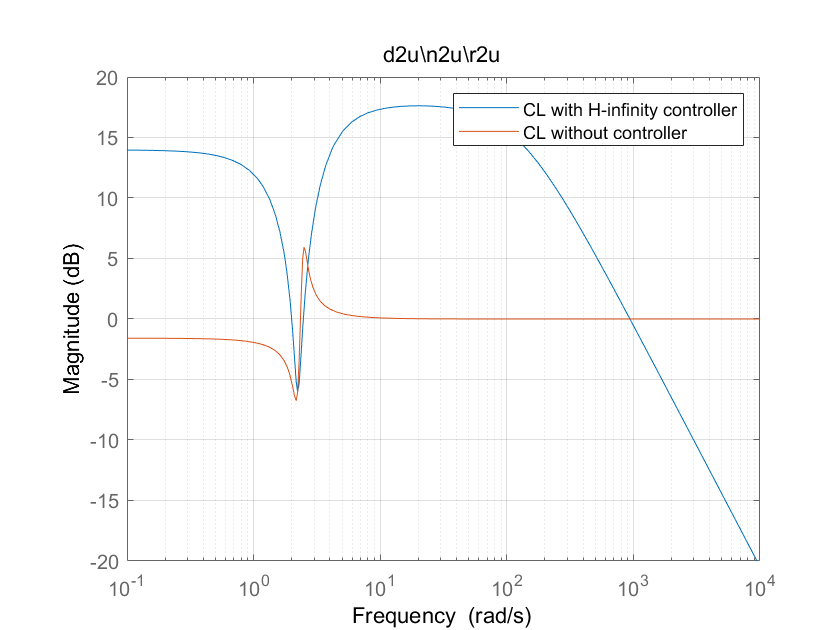

wb=5;

den2=[1/M wb];
num2=[1 wb*sse];

gamma =       0.92695


State-space model with 1 outputs, 1 inputs, and 3 states.


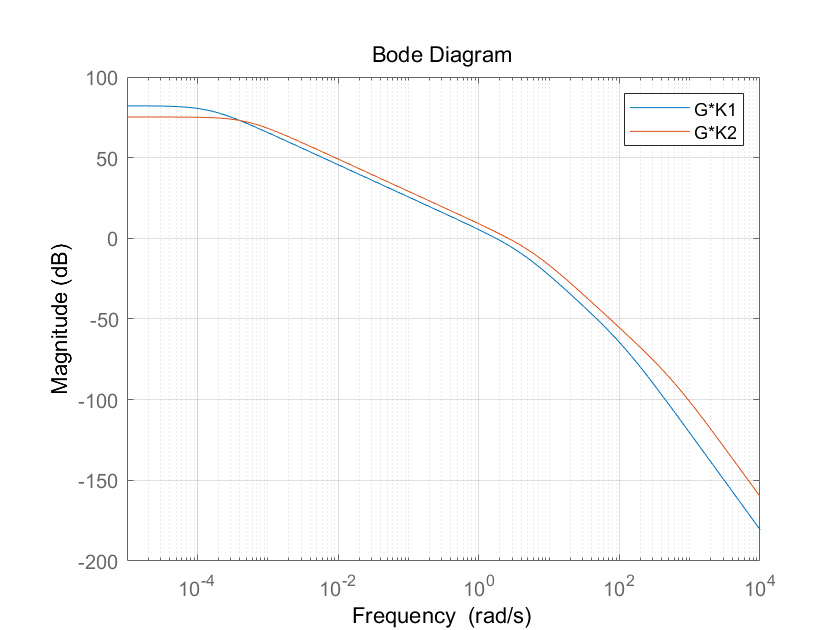

W1_=tf(den2,num2); 
W2_=0.1;% 0.01\ 0.1\1
P2 = augw(G,W1_,W2_,W3);
[K2,CL2,gamma2] = hinfsyn(P2,1,1);
size(K2)
bodemag(G*K,G*K2)
legend('G*K1','G*K2')
grid on 


If we only increse the wb, system is faster while the control input contains more noise

If we increse W2, which is the penalizing term of control input, the control signal will be smaller